# Lab 1 – Image as a 2D Signal

Course: Digital Signal Processing

**Lecture: 9 – Image Processing LabsObjective**

The purpose of this lab is to investigate how digital images behave as two-dimensional signals.

The experiment examines quantization, dynamic range, histogram enhancement, gamma correction, and image sampling using MATLAB.

The results will be compared visually to understand how these operations affect image quality and the visibility of details.

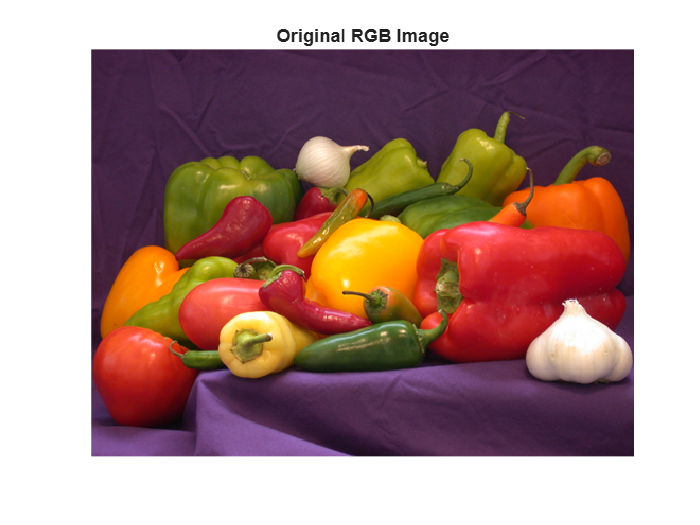


%% Lab 1: Image as a 2D Signal
% Section 0: Load and Inspect an Image

close all;
clear;
clc;

% Load peppers.png if available
if exist('peppers.png', 'file')
    I_rgb = imread('peppers.png');
else
    % Use cameraman.tif as a fallback
    I_rgb = repmat(imread('cameraman.tif'), 1, 1, 3);
end

% Display original image
figure;
imshow(I_rgb);
title('Original RGB Image');

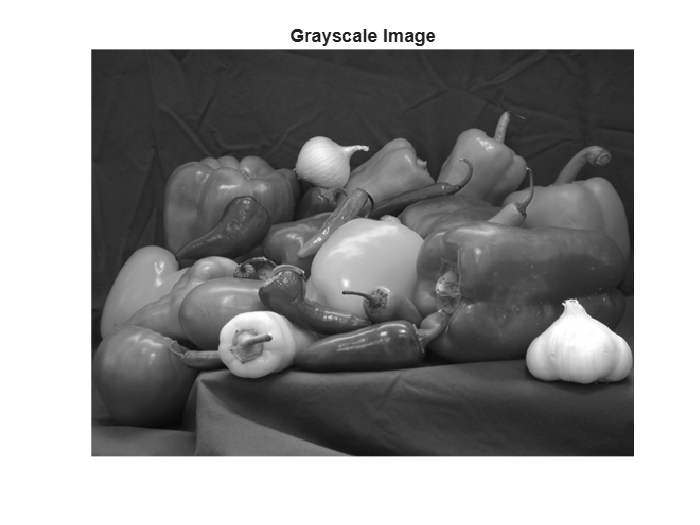


% Convert image to grayscale
if size(I_rgb, 3) == 3
    I = rgb2gray(I_rgb);
else
    I = I_rgb;
end

% Display grayscale image
figure;
imshow(I);
title('Grayscale Image');


% Print basic image information
fprintf('Class: %s | Range: [%g, %g] | Size: %d x %d\n', ...
    class(I), ...
    double(min(I(:))), ...
    double(max(I(:))), ...
    size(I,1), size(I,2));

Class: uint8 | Range: [8, 255] | Size: 384 x 512


**Section 0 – Image Inspection**

The image was loaded into MATLAB and displayed in its original form. It was then converted to grayscale to represent the image using a single intensity value at each pixel.

A grayscale image can be considered a two-dimensional signal, where the pixel position represents spatial coordinates and the pixel value represents intensity.

The image dimensions, data type, and intensity range were examined to understand how the image is stored digitally.

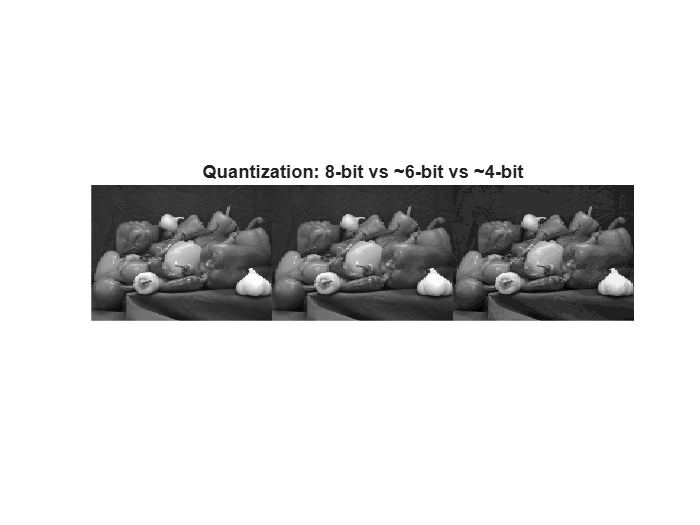


%% 1) Quantization and Dynamic Range

% Original 8-bit image
I8 = I;

% Reduce intensity levels to approximately 6 bits
I6 = uint8(floor(double(I)/4)*4);

% Reduce intensity levels to approximately 4 bits
I4 = uint8(floor(double(I)/16)*16);

% Display comparison
figure;
montage({I8, I6, I4}, 'Size', [1 3]);

title('Quantization: 8-bit vs ~6-bit vs ~4-bit');

**Section 1 – Quantization and Dynamic Range**

The original grayscale image uses 8-bit intensity values, allowing 256 possible gray levels.

The image was quantized to approximately 6 bits and 4 bits by increasing the intensity step size.

With 6-bit quantization, most image details remain recognizable, although some smooth intensity transitions become less precise.

With 4-bit quantization, the reduction in gray levels is more noticeable. Gradual changes in brightness may appear as visible bands, an effect known as posterization.

This demonstrates how reducing bit depth decreases intensity resolution and can affect image quality.

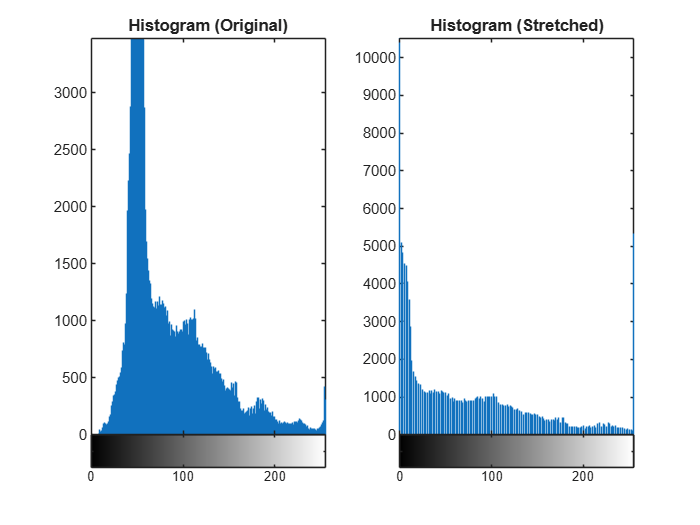


%% 2) Histogram and Contrast Stretching

% Display original histogram
figure;

subplot(1,2,1);
imhist(I);
title('Histogram (Original)');

% Normalize image intensities to [0,1]
I_norm = mat2gray(I);

% Apply contrast stretching
I_stretch = imadjust(I, [0.2 0.8], [0 1]);

% Display stretched histogram
subplot(1,2,2);
imhist(I_stretch);
title('Histogram (Stretched)');

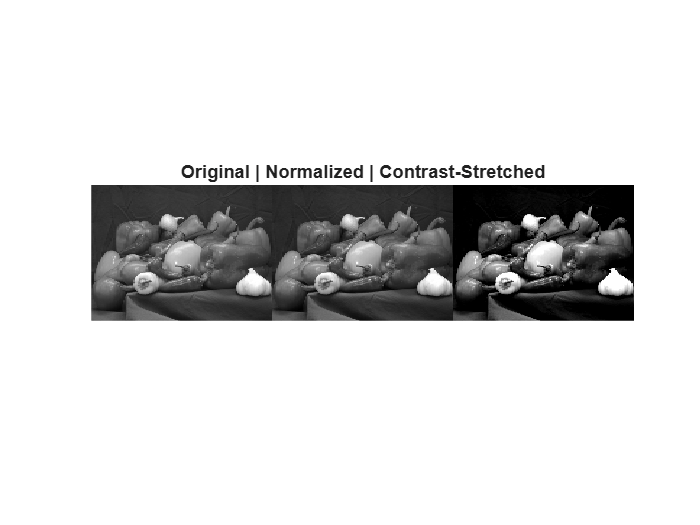


% Compare the images
figure;
montage({I, im2uint8(I_norm), im2uint8(I_stretch)}, ...
    'Size', [1 3]);

title('Original | Normalized | Contrast-Stretched');

**Section 2 – Histogram and Contrast Stretching**

The histogram shows how grayscale pixel intensities are distributed in the image. It helps identify whether most pixels are concentrated in dark, middle, or bright intensity ranges.

The image was normalized using `mat2gray`, which maps the minimum and maximum intensity values to the range from 0 to 1.

Contrast stretching was then applied using `imadjust` with the input interval [0.2, 0.8]. This expands the middle intensity range and can make differences between image regions more visible.

The stretched histogram shows how the intensity distribution changes after adjustment. However, very dark and very bright values may be clipped, which can cause some details to disappear.

This experiment demonstrates how changing the intensity range affects image contrast and the visibility of details.

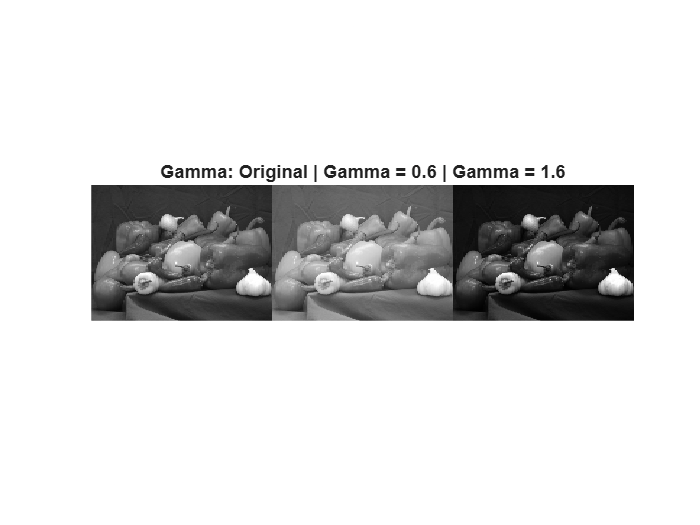


%% 3) Gamma Correction (Nonlinear Amplitude Scaling)

% Gamma < 1 brightens the image
I_gamma_low = imadjust(I, [], [], 0.6);

% Gamma > 1 darkens the image
I_gamma_high = imadjust(I, [], [], 1.6);

% Display comparison
figure;
montage({I, I_gamma_low, I_gamma_high}, 'Size', [1 3]);

title('Gamma: Original | Gamma = 0.6 | Gamma = 1.6');

**Section 3 – Gamma Correction**

Gamma correction was applied to the grayscale image using two different gamma values: 0.6 and 1.6.

With gamma = 0.6, the image becomes brighter because lower intensity values are increased. This can make details in darker regions easier to see.

With gamma = 1.6, the image becomes darker because intermediate intensity values are reduced.

Unlike linear contrast stretching, gamma correction uses a nonlinear transformation to adjust image brightness.

This experiment demonstrates how different gamma values affect the appearance of an image while preserving its dimensions.

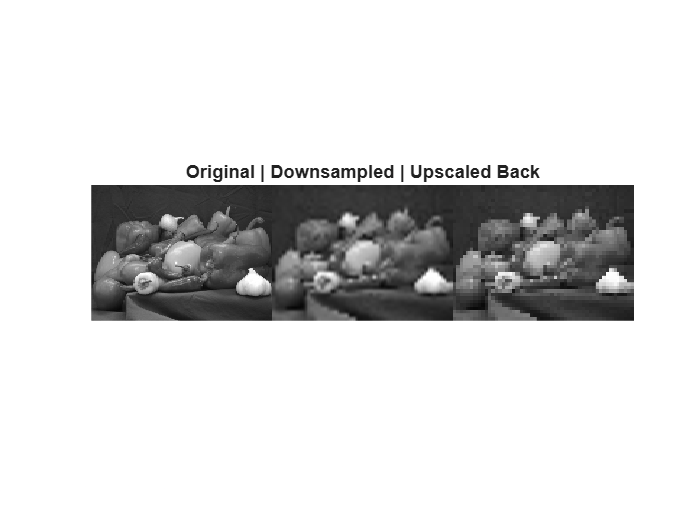


%% 4) Sampling and Aliasing (Downsample Then Upsample)

% Reduce image to 10% of its original size
scale = 0.1;

% Downsample using nearest-neighbor interpolation
I_small = imresize(I, scale, 'nearest');

% Upsample back to the original dimensions
I_back = imresize(I_small, size(I), 'nearest');

% Display the comparison
figure;
montage({I, I_small, I_back}, 'Size', [1 3]);

title('Original | Downsampled | Upscaled Back');

**Section 4 – Sampling and Aliasing**

The grayscale image was reduced to 10% of its original dimensions using nearest-neighbor interpolation. It was then enlarged back to its original size.

The enlarged image appears more pixelated, and some fine details are lost because fewer pixels were used to represent the original image.

Aggressive downsampling can also cause aliasing when high-frequency image details are sampled at an insufficient rate. According to the Nyquist principle, the sampling frequency must be more than twice the highest frequency present in the signal to avoid aliasing.

Nearest-neighbor interpolation does not remove high-frequency components before downsampling, which can result in visual artifacts.

This experiment demonstrates how reducing spatial resolution affects image quality and why appropriate sampling is important in digital image processing.

## Section 6 – Short Reflections

**1. How does bit depth affect visible banding and posterization?**

Bit depth determines how many intensity levels can be represented in a digital image.

The original 8-bit image contains 256 possible gray levels, while the approximately 6-bit and 4-bit images contain 64 and 16 levels.

Reducing the bit depth makes intensity transitions less smooth. With 4-bit quantization, differences between neighboring gray levels become more noticeable, potentially producing visible bands or posterization.

This shows that lower bit depth reduces the precision of pixel intensity representation.

**2. How does contrast stretching change the histogram and visibility of details?**

Contrast stretching changes the distribution of pixel intensities by expanding a selected intensity range.

In this experiment, the input range from 0.2 to 0.8 was mapped to the full output range from 0 to 1.

This increases the separation between pixel intensities in the selected range, which can make certain image details easier to distinguish.

However, pixels outside the selected range are clipped to black or white, potentially causing information loss in very dark or bright areas.

**3. Why does aggressive downsampling cause aliasing? Explain using the Nyquist principle.**

Aggressive downsampling reduces the number of pixels used to represent an image.

When the image was reduced to 10% of its original width and height, much of its spatial information was discarded.

According to the Nyquist principle, the sampling frequency must be more than twice the highest frequency present in the signal to avoid aliasing.

If fine image details contain frequencies above the new Nyquist limit, they can appear incorrectly as lower-frequency patterns.

Because nearest-neighbor downsampling does not apply an anti-aliasing filter, these artifacts may occur. Enlarging the image afterward cannot recover the original details.